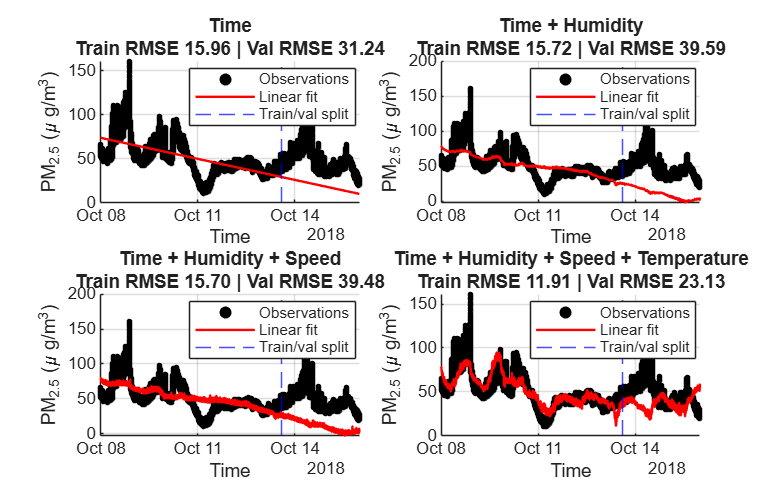

% load in the data 
clear; clc;

short_term = load('short_term_foshan_train_val.mat');
long_term = load('long_term_tianjin_train_val.mat');

data_mobile_s = short_term.data_mobile;
data_static_s = short_term.data_static;

data_mobile_l = long_term.data_mobile;
data_static_l = long_term.data_static;

% feature charts for short-term data
feats  = {'hmd','spd','tmp'};
labels = {'Humidity (%)','Wind speed (m/s)','Temperature (°C)'};

%% Choose first static sensor
T = sortrows(data_static_s{1}, 'time');
T = rmmissing(T, 'DataVariables', {'time','hmd','spd','tmp','pm2d5'});

time    = T.time;
pm2d5   = T.pm2d5;
time_num = hours(time - time(1));      % hours since start (keeps the fit well-conditioned)

X = [time_num, T.hmd, T.spd, T.tmp];

%% Chronological train / validation split (first 70% train, last 30% validation)
n = height(T);
idx_train = false(n,1);
idx_train(1:floor(0.7*n)) = true;
idx_validation = ~idx_train;

%% Fit with progressively more features
features = {'Time', 'Time + Humidity', 'Time + Humidity + Speed', ...
    'Time + Humidity + Speed + Temperature'};

figure('Name','Additional features','Position',[80,60,1100,700]);

trainRMSE = zeros(1,4);
valRMSE   = zeros(1,4);

for i = 1:4
    subplot(2,2,i)
    scatter(time, pm2d5, 8, 'k', 'filled'); hold on

    A    = [ones(n,1), X(:,1:i)];               % intercept + first i features
    beta = A(idx_train,:) \ pm2d5(idx_train);   % least squares on training rows only
    yhat = A * beta;

    trainRMSE(i) = rmse(pm2d5(idx_train),      yhat(idx_train));
    valRMSE(i)   = rmse(pm2d5(idx_validation), yhat(idx_validation));

    plot(time, yhat, 'r', 'LineWidth', 1.2);
    xline(time(find(idx_train, 1, 'last')), '--b');   % train/validation boundary
    xlabel('Time'); ylabel('PM_{2.5} (\mu g/m^3)'); grid on
    title(sprintf('%s\nTrain RMSE %.2f | Val RMSE %.2f', ...
        features{i}, trainRMSE(i), valRMSE(i)));
    legend('Observations','Linear fit','Train/val split','Location','best');
end

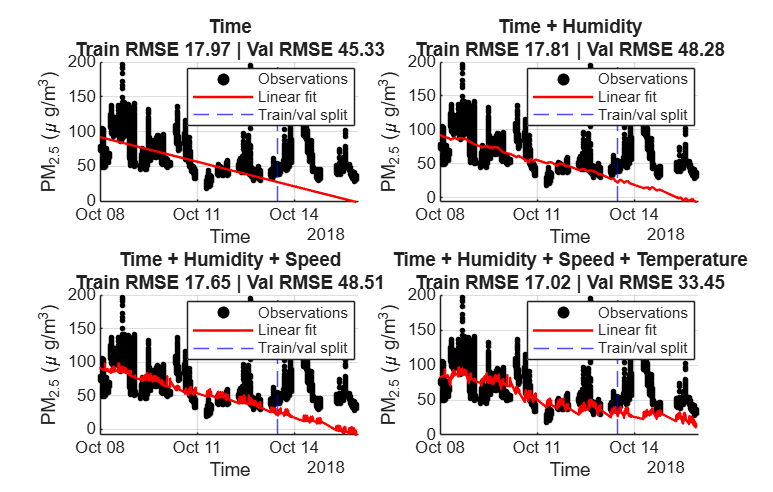

%% Choose one mobile sensor (short-term)
k = 1;                                            % change to try other mobile sensors
T = sortrows(data_mobile_s{k}, 'time');
T = rmmissing(T, 'DataVariables', {'time','hmd','spd','tmp','pm2d5'});

time     = T.time;
pm2d5    = T.pm2d5;
time_num = hours(time - time(1));                 % hours since start

X = [time_num, T.hmd, T.spd, T.tmp];

%% Chronological train / validation split (first 70% / last 30%)
n = height(T);
idx_train = false(n,1);  idx_train(1:floor(0.7*n)) = true;
idx_validation = ~idx_train;

%% Fit with progressively more features
features = {'Time', 'Time + Humidity', 'Time + Humidity + Speed', ...
    'Time + Humidity + Speed + Temperature'};

figure('Name','Mobile sensor: additional features','Position',[80,60,1100,700]);

trainRMSE = zeros(1,4);
valRMSE   = zeros(1,4);

for i = 1:4
    subplot(2,2,i)
    scatter(time, pm2d5, 8, 'k', 'filled'); hold on

    A    = [ones(n,1), X(:,1:i)];
    beta = A(idx_train,:) \ pm2d5(idx_train);
    yhat = A * beta;

    trainRMSE(i) = rmse(pm2d5(idx_train),      yhat(idx_train));
    valRMSE(i)   = rmse(pm2d5(idx_validation), yhat(idx_validation));

    plot(time, yhat, 'r', 'LineWidth', 1.2);
    xline(time(find(idx_train, 1, 'last')), '--b');
    xlabel('Time'); ylabel('PM_{2.5} (\mu g/m^3)'); grid on
    title(sprintf('%s\nTrain RMSE %.2f | Val RMSE %.2f', ...
        features{i}, trainRMSE(i), valRMSE(i)));
    legend('Observations','Linear fit','Train/val split','Location','best');
end

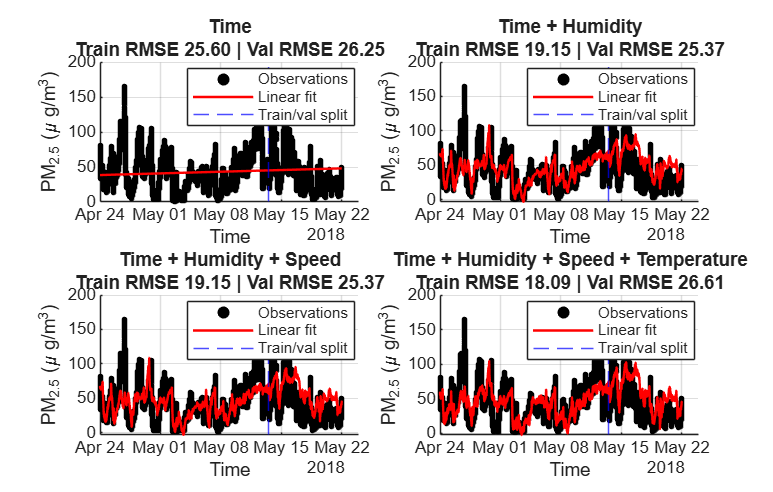

% long-term
%% Choose first static sensor
T = sortrows(data_static_l{1}, 'time');
T = rmmissing(T, 'DataVariables', {'time','hmd','spd','tmp','pm2d5'});

time    = T.time;
pm2d5   = T.pm2d5;
time_num = hours(time - time(1));      % hours since start (keeps the fit well-conditioned)

X = [time_num, T.hmd, T.spd, T.tmp];

%% Chronological train / validation split (first 70% train, last 30% validation)
n = height(T);
idx_train = false(n,1);
idx_train(1:floor(0.7*n)) = true;
idx_validation = ~idx_train;

%% Fit with progressively more features
features = {'Time', 'Time + Humidity', 'Time + Humidity + Speed', ...
    'Time + Humidity + Speed + Temperature'};

figure('Name','Additional features','Position',[80,60,1100,700]);

trainRMSE = zeros(1,4);
valRMSE   = zeros(1,4);

for i = 1:4
    subplot(2,2,i)
    scatter(time, pm2d5, 8, 'k', 'filled'); hold on

    A    = [ones(n,1), X(:,1:i)];               % intercept + first i features
    beta = A(idx_train,:) \ pm2d5(idx_train);   % least squares on training rows only
    yhat = A * beta;

    trainRMSE(i) = rmse(pm2d5(idx_train),      yhat(idx_train));
    valRMSE(i)   = rmse(pm2d5(idx_validation), yhat(idx_validation));

    plot(time, yhat, 'r', 'LineWidth', 1.2);
    xline(time(find(idx_train, 1, 'last')), '--b');   % train/validation boundary
    xlabel('Time'); ylabel('PM_{2.5} (\mu g/m^3)'); grid on
    title(sprintf('%s\nTrain RMSE %.2f | Val RMSE %.2f', ...
        features{i}, trainRMSE(i), valRMSE(i)));
    legend('Observations','Linear fit','Train/val split','Location','best');
end

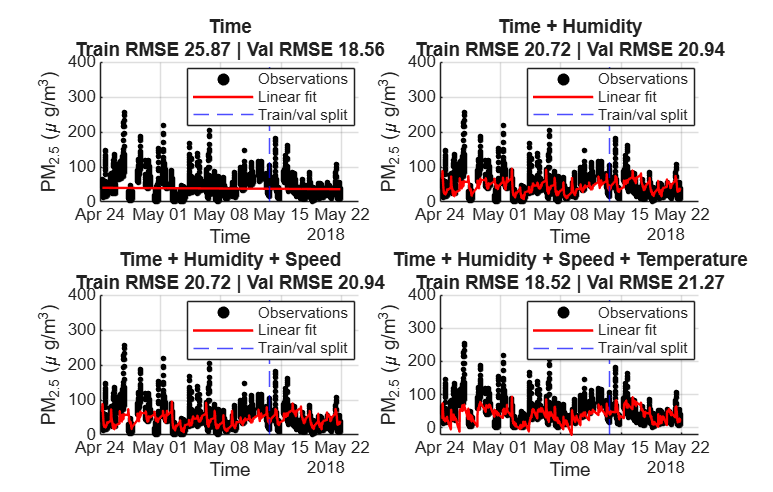

%% Choose one mobile sensor (short-term)
k = 1;                                            % change to try other mobile sensors
T = sortrows(data_mobile_l{k}, 'time');
T = rmmissing(T, 'DataVariables', {'time','hmd','spd','tmp','pm2d5'});

time     = T.time;
pm2d5    = T.pm2d5;
time_num = hours(time - time(1));                 % hours since start

X = [time_num, T.hmd, T.spd, T.tmp];

%% Chronological train / validation split (first 70% / last 30%)
n = height(T);
idx_train = false(n,1);  idx_train(1:floor(0.7*n)) = true;
idx_validation = ~idx_train;

%% Fit with progressively more features
features = {'Time', 'Time + Humidity', 'Time + Humidity + Speed', ...
    'Time + Humidity + Speed + Temperature'};

figure('Name','Mobile sensor: additional features','Position',[80,60,1100,700]);

trainRMSE = zeros(1,4);
valRMSE   = zeros(1,4);

for i = 1:4
    subplot(2,2,i)
    scatter(time, pm2d5, 8, 'k', 'filled'); hold on

    A    = [ones(n,1), X(:,1:i)];
    beta = A(idx_train,:) \ pm2d5(idx_train);
    yhat = A * beta;

    trainRMSE(i) = rmse(pm2d5(idx_train),      yhat(idx_train));
    valRMSE(i)   = rmse(pm2d5(idx_validation), yhat(idx_validation));

    plot(time, yhat, 'r', 'LineWidth', 1.2);
    xline(time(find(idx_train, 1, 'last')), '--b');
    xlabel('Time'); ylabel('PM_{2.5} (\mu g/m^3)'); grid on
    title(sprintf('%s\nTrain RMSE %.2f | Val RMSE %.2f', ...
        features{i}, trainRMSE(i), valRMSE(i)));
    legend('Observations','Linear fit','Train/val split','Location','best');
end